## 0. 형상

## [작성중]1. FEM-열회로

###  Part1 - FEM Gap (  1Gap(Resistor) + 2 FEM)

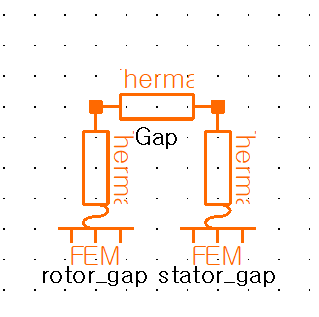

#### Thermal Resistor

case1)로터와 고정자처럼 분리된 두 물체 사이에 열이 전달되는 경우 열 회로의 열 저항 부품을 사용합니다. 

### Part2 :  Housing (1 Cap+3 Resistor + 1 Convection + 1FEM)

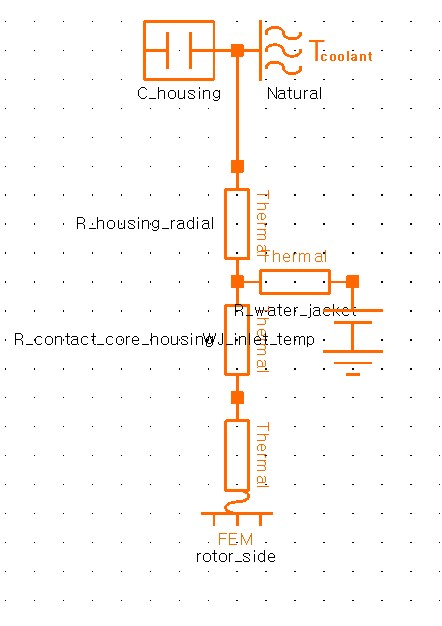

General Contact

Thermal Conduction (Cylinder) 

Natural & or Constant Resistance

1.R_contact_core_housing 

Housing 과 접하는 회전자 Core 접촉저항 설정

#### Thermal Resistor (contact & conduction & Convection 

#### R_housing_radial

3D모델대신 회전자 하우징의 방사방향 열저항을 치수정보를 이용해 산정 

열저항과 마찬가지로  3D형상대신 치수정보로 산정

### Part3  - ( 8 Resistor + 1 Cap + 7 FEM)

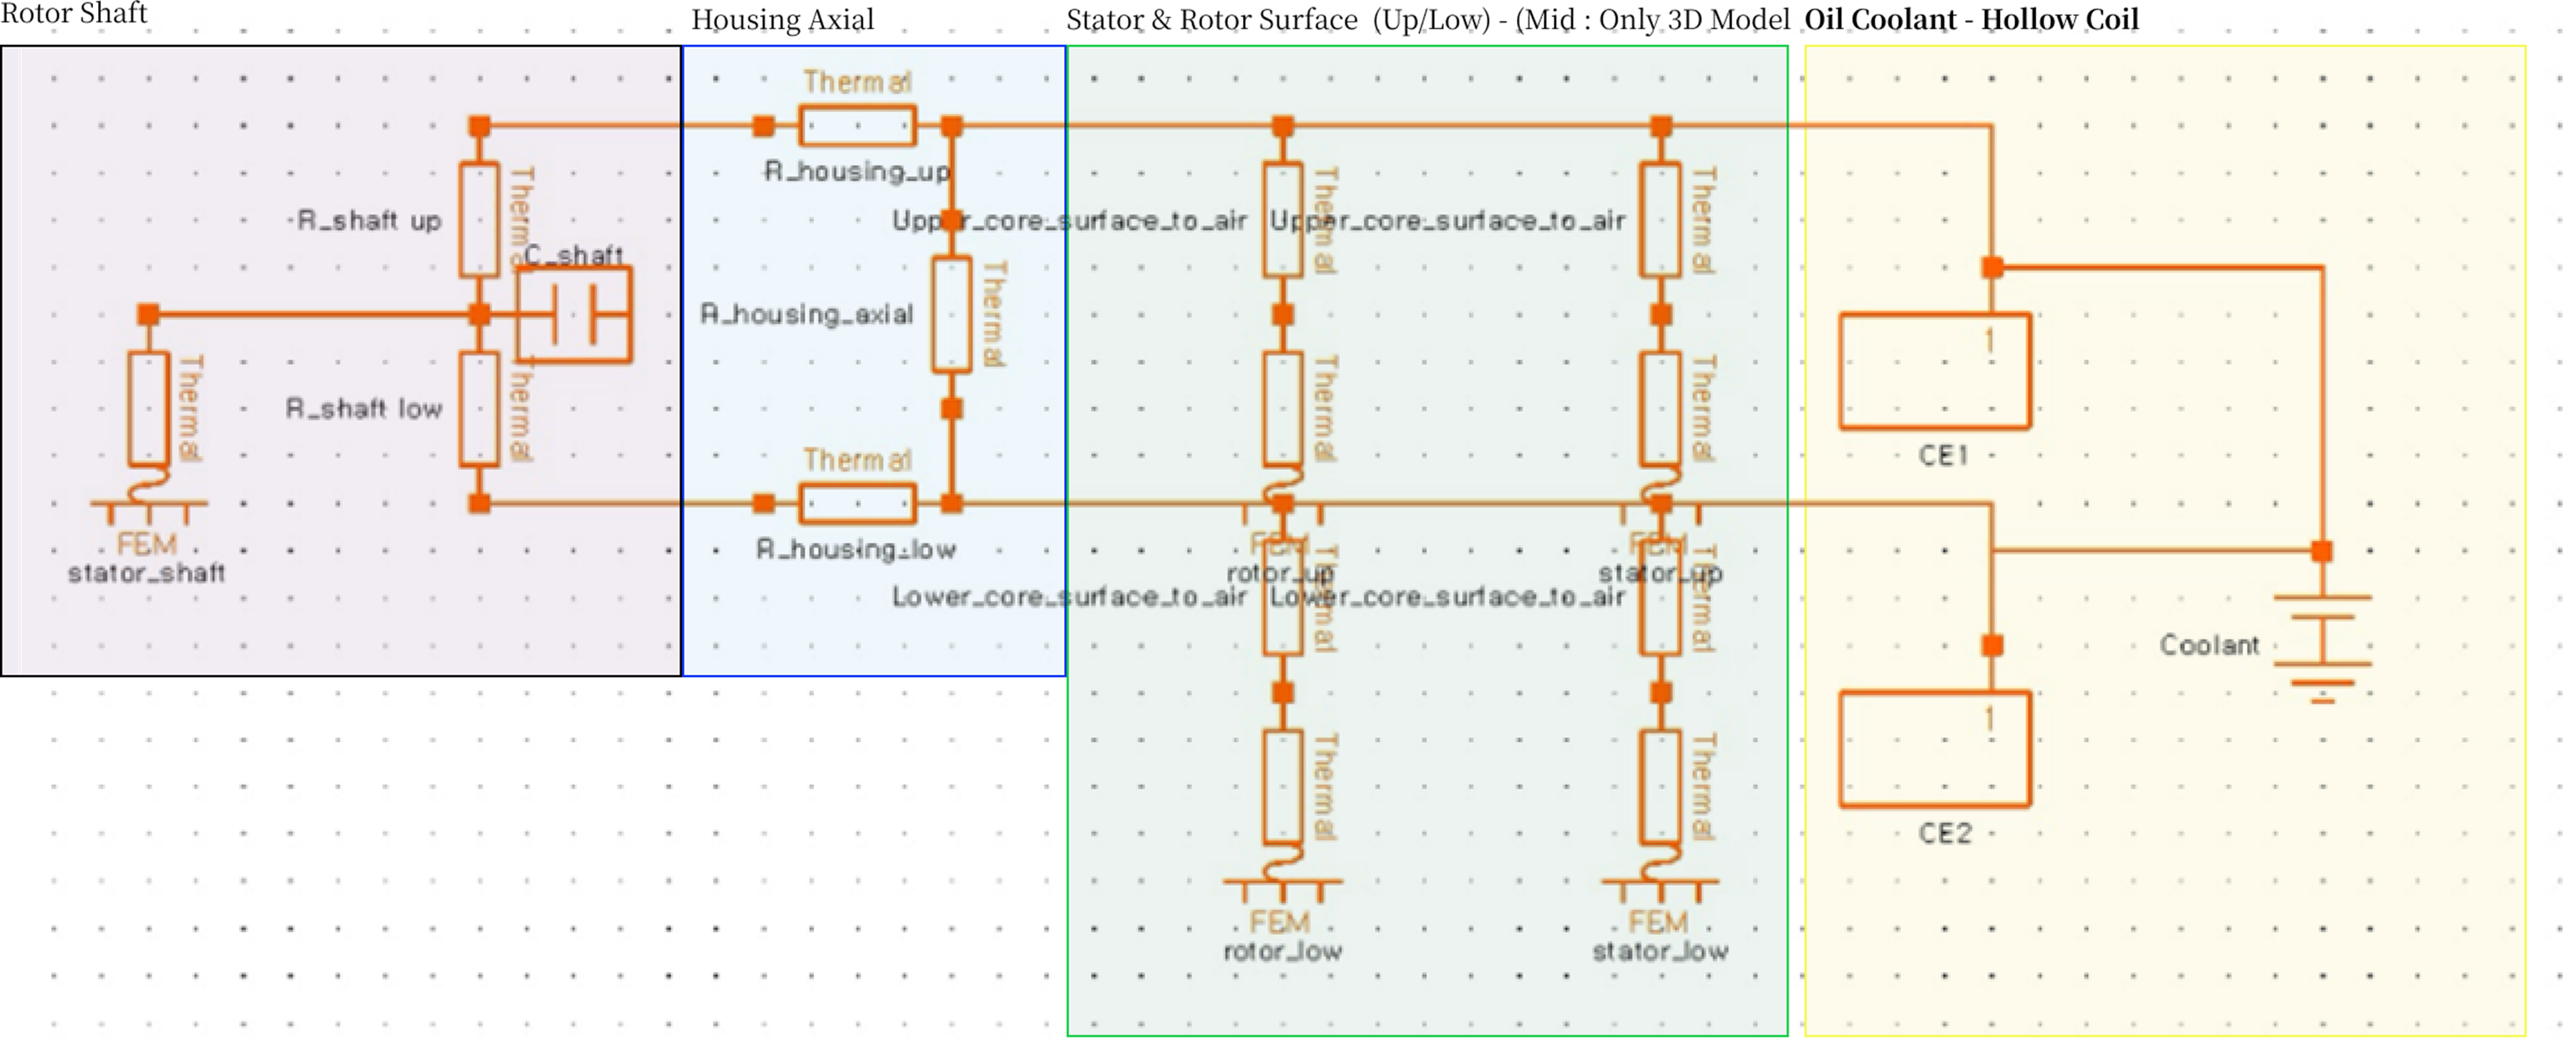

#### Rotor Shaft

3D 모델이 있는 Rotor와 3D모델이 없는 Shaft간의 열저항과 Cap 산정

FEM- rotor_shaft

R_shaft_up & low

C_shaft

#### Housing

R_housing_up & low

R_housing_axial

#### Core

Upper_core_surface_to_air

FEM rotor up

Lower_core_surface_to_air

FEM rotor low

Upper_core_surface_to_air

FEM stator up

Lower_core_surface_to_air

FEM stator low

#### Coil Direct Cooling

% Thermal Resistor
% coilend_surface_area     =           
% coilend_area  
% RthCoilEnd
% RthConvCoilEnd


#### Thermal Area

## 2. 결과 (+민감도분석 : 코일대류계수, 코일대류면적) 

### 2.1 350P300s Model  (자석손실미적용)

Model :PMSG_350P_300S_v1_case1Thermal_10

###     Study1  End Coil HTC 민감도 분석 (End Coil Oil Spray)

 Condution 조건

- Equivalent Temperature Boundary 면 : Only Top

- 손실입력 : 동손만 989kw

Rcoil_Conv=[0.01;0.01;0.01;0.001]
CoilTemp_avg=[300.32330817;289.671855724;289.647212742;278.497914671]
plot(Rcoil_Conv,CoilTemp_avg)

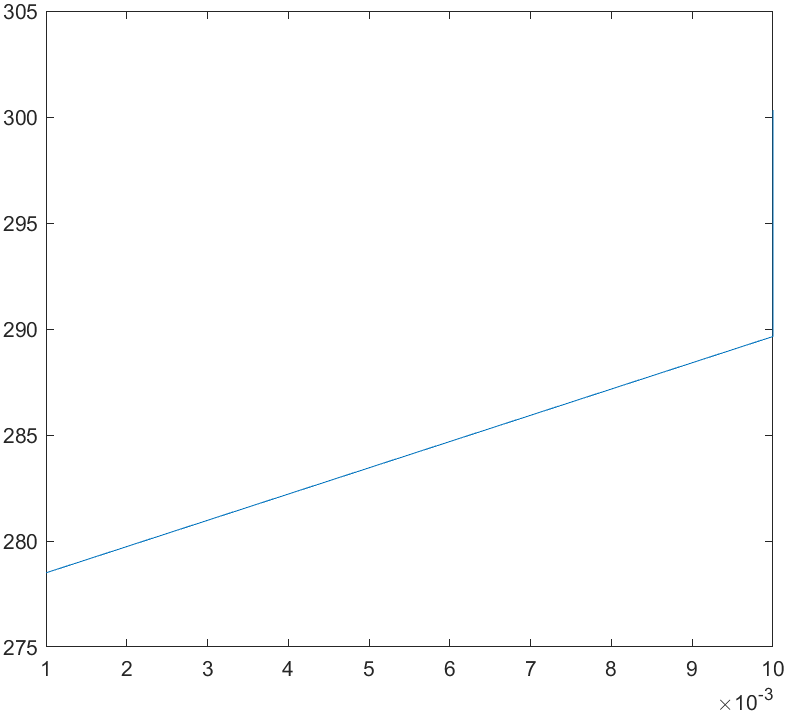


$$\begin{array}{|l|l|}
\hline \text { RthConvCoilEnd } & \text { Magnet Constant } \\
\hline 0.01 & 123600 \\
\hline 0.01 & 241.9 \\
\hline 0.01 & 2.3542 \\
\hline 0.001 & 241.9 \\
\hline
\end{array}$$


###     Study2 -  Hollow Conductor  

Condution 조건 Equivalent Temperature Boundary 면   TopN2Side

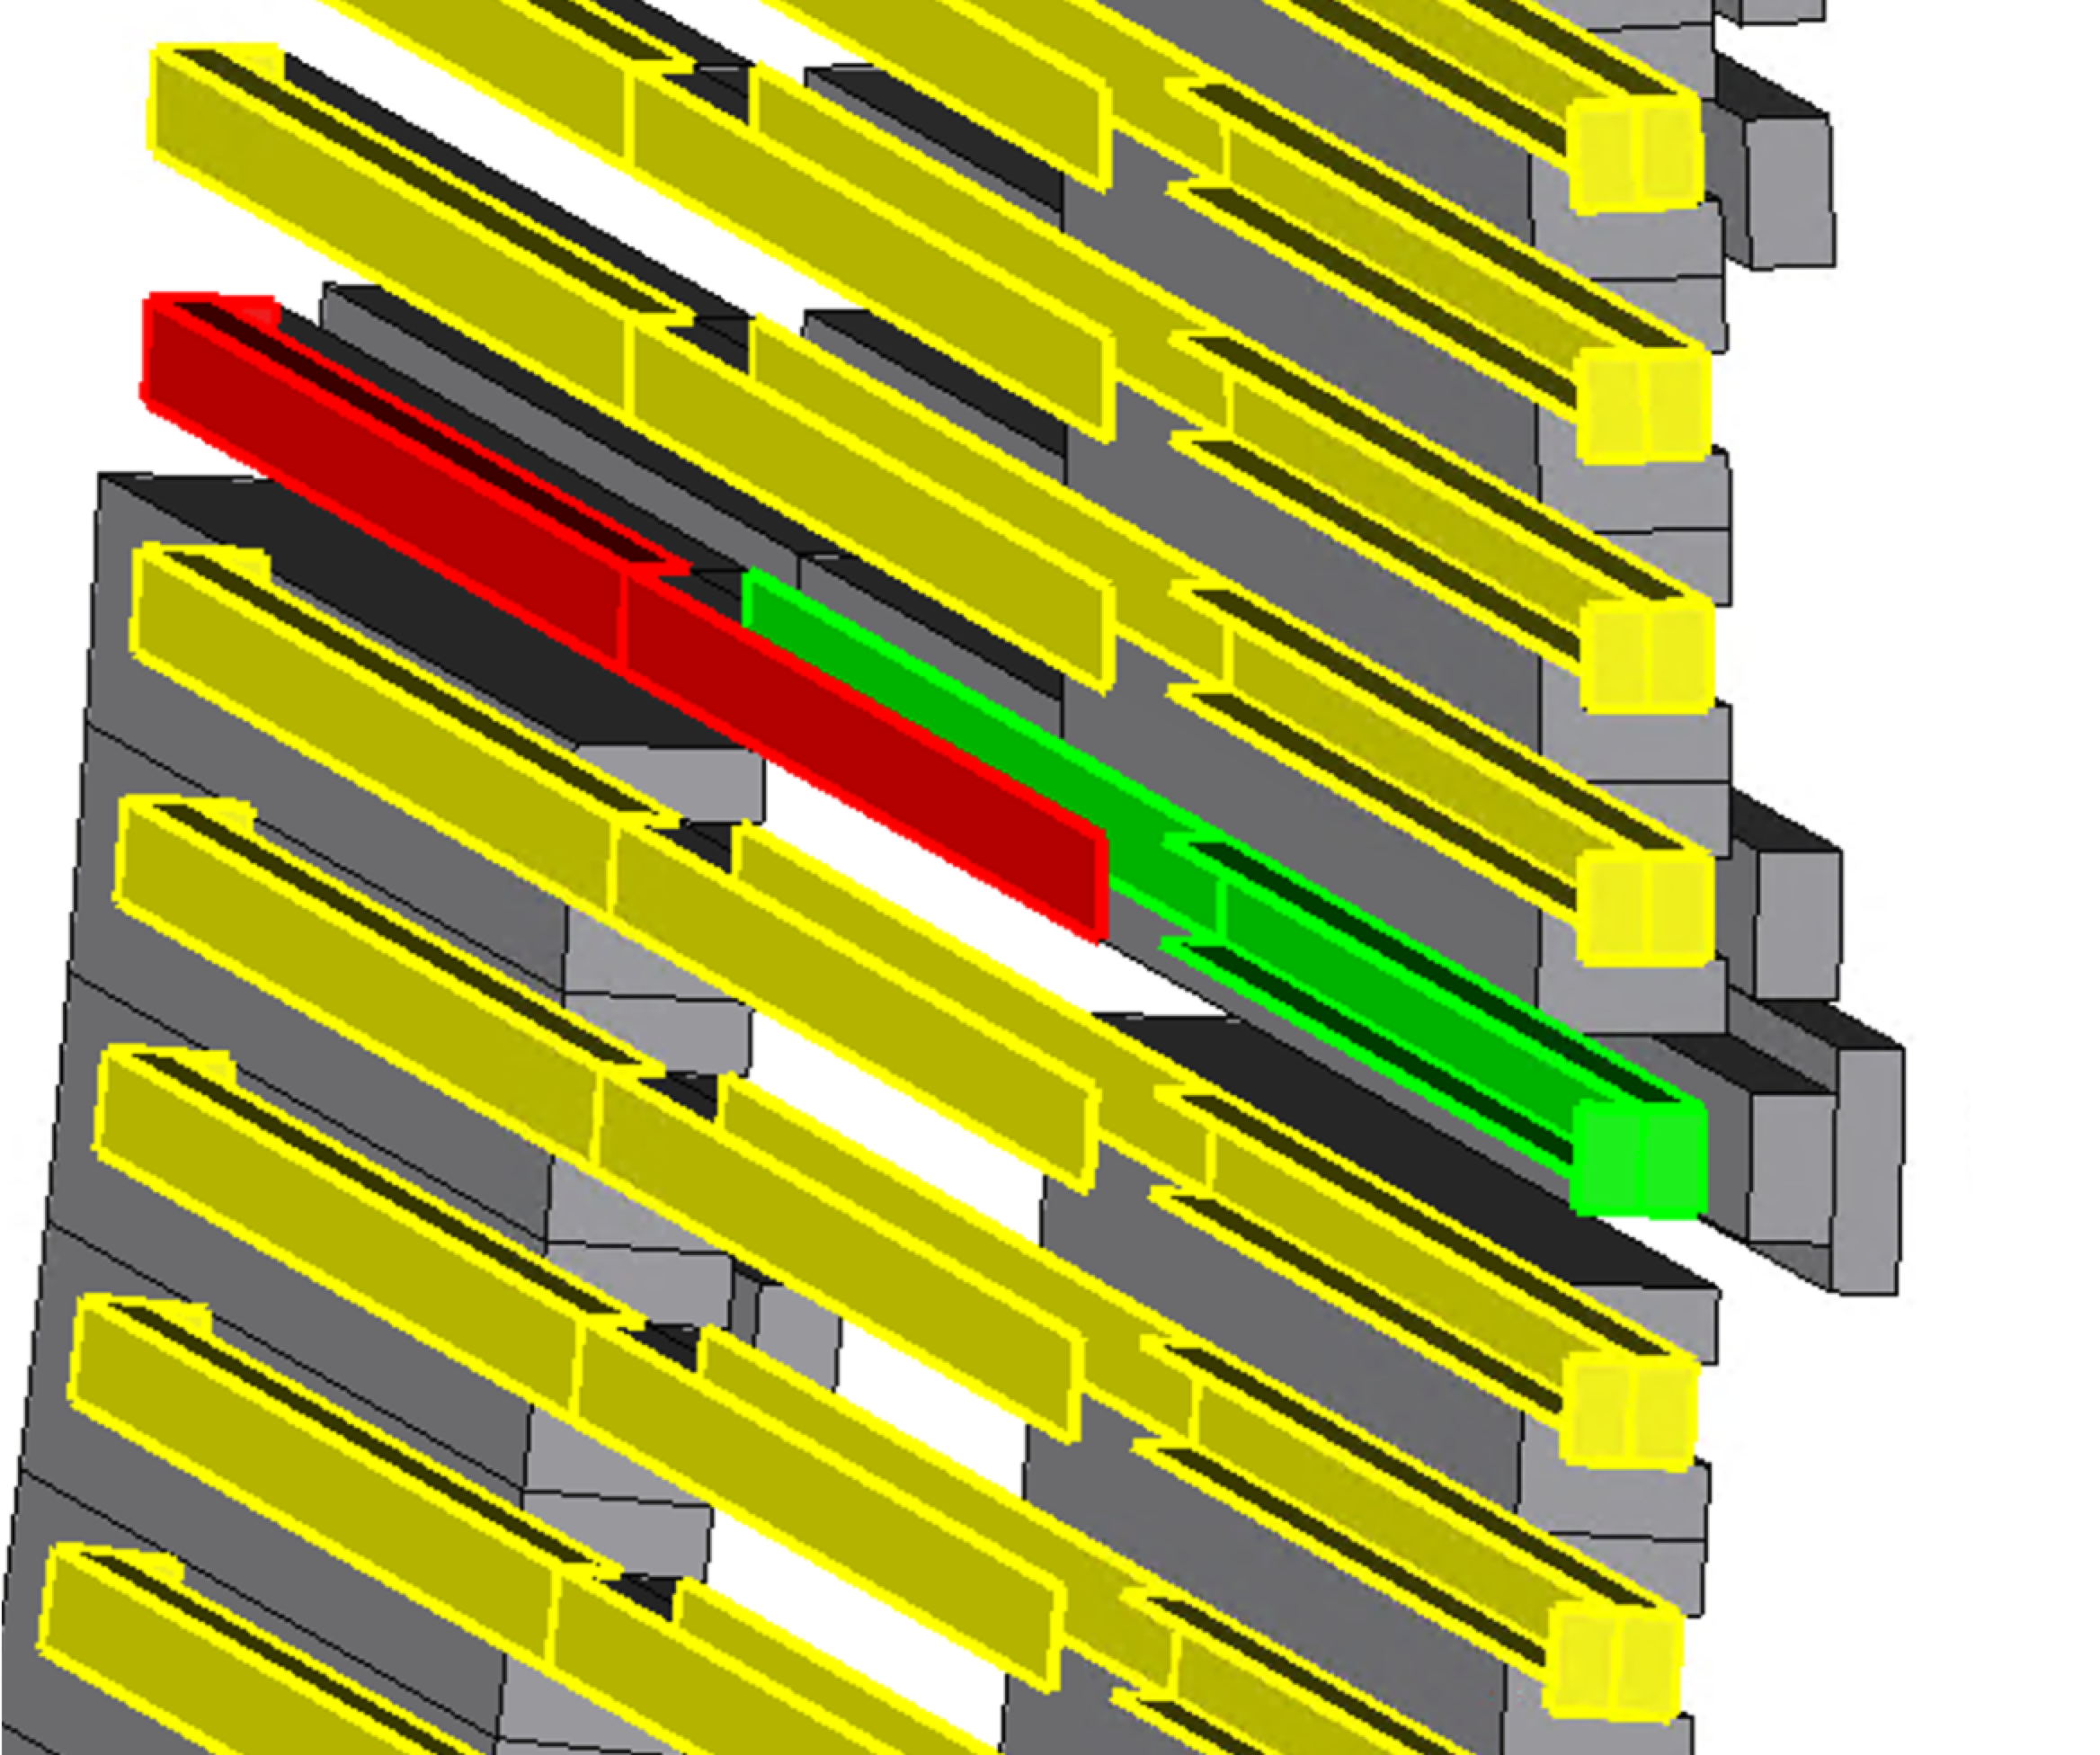

#### study 2.1 대류 열저항 조건별

Rcoil_Conv=[0.001 0.01 0.1 10]'
CoilTemp_avg=[160.060817848	173.454146447	294.073414916	1396.95058495]'
plot(Rcoil_Conv,CoilTemp_avg)

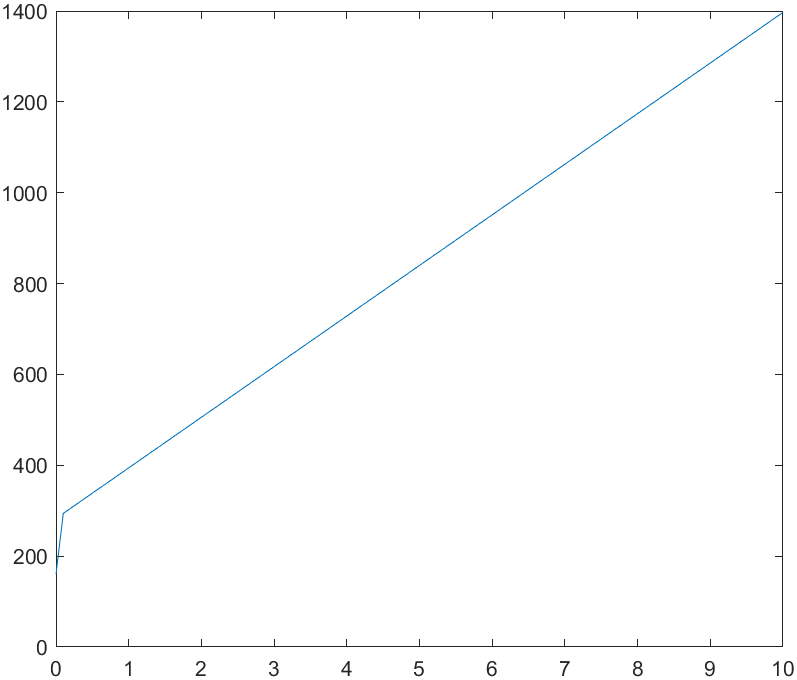

#### study 2.2 - 대류열저항조건 고정, 냉각수온도 변경

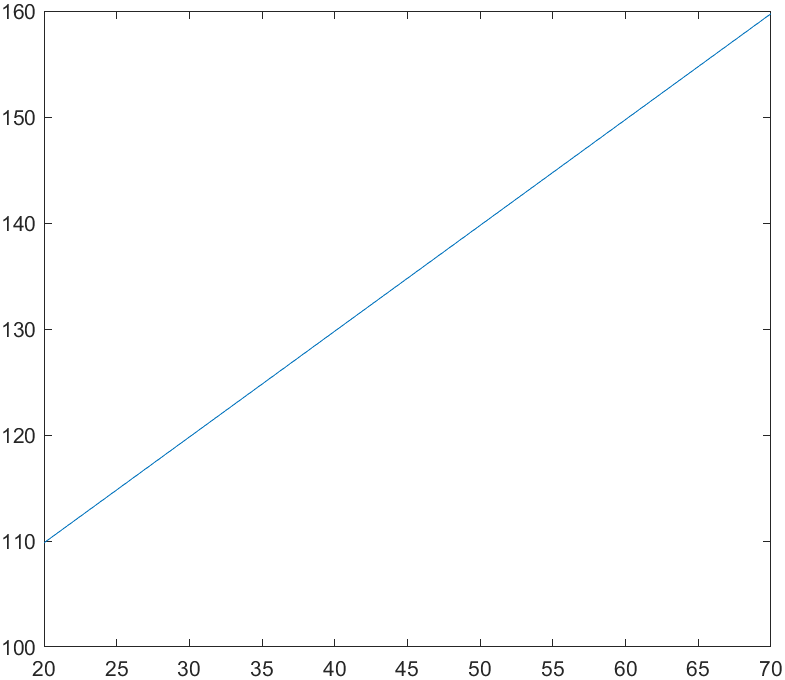

Rcoil_Conv=0.001
Tcoolant=[20 30 40 50 60 70]'
Conduc=[	109.828596353	119.812644912	129.796703159	139.780470311	149.764322405	159.748149926]'
plot(Tcoolant,Conduc)

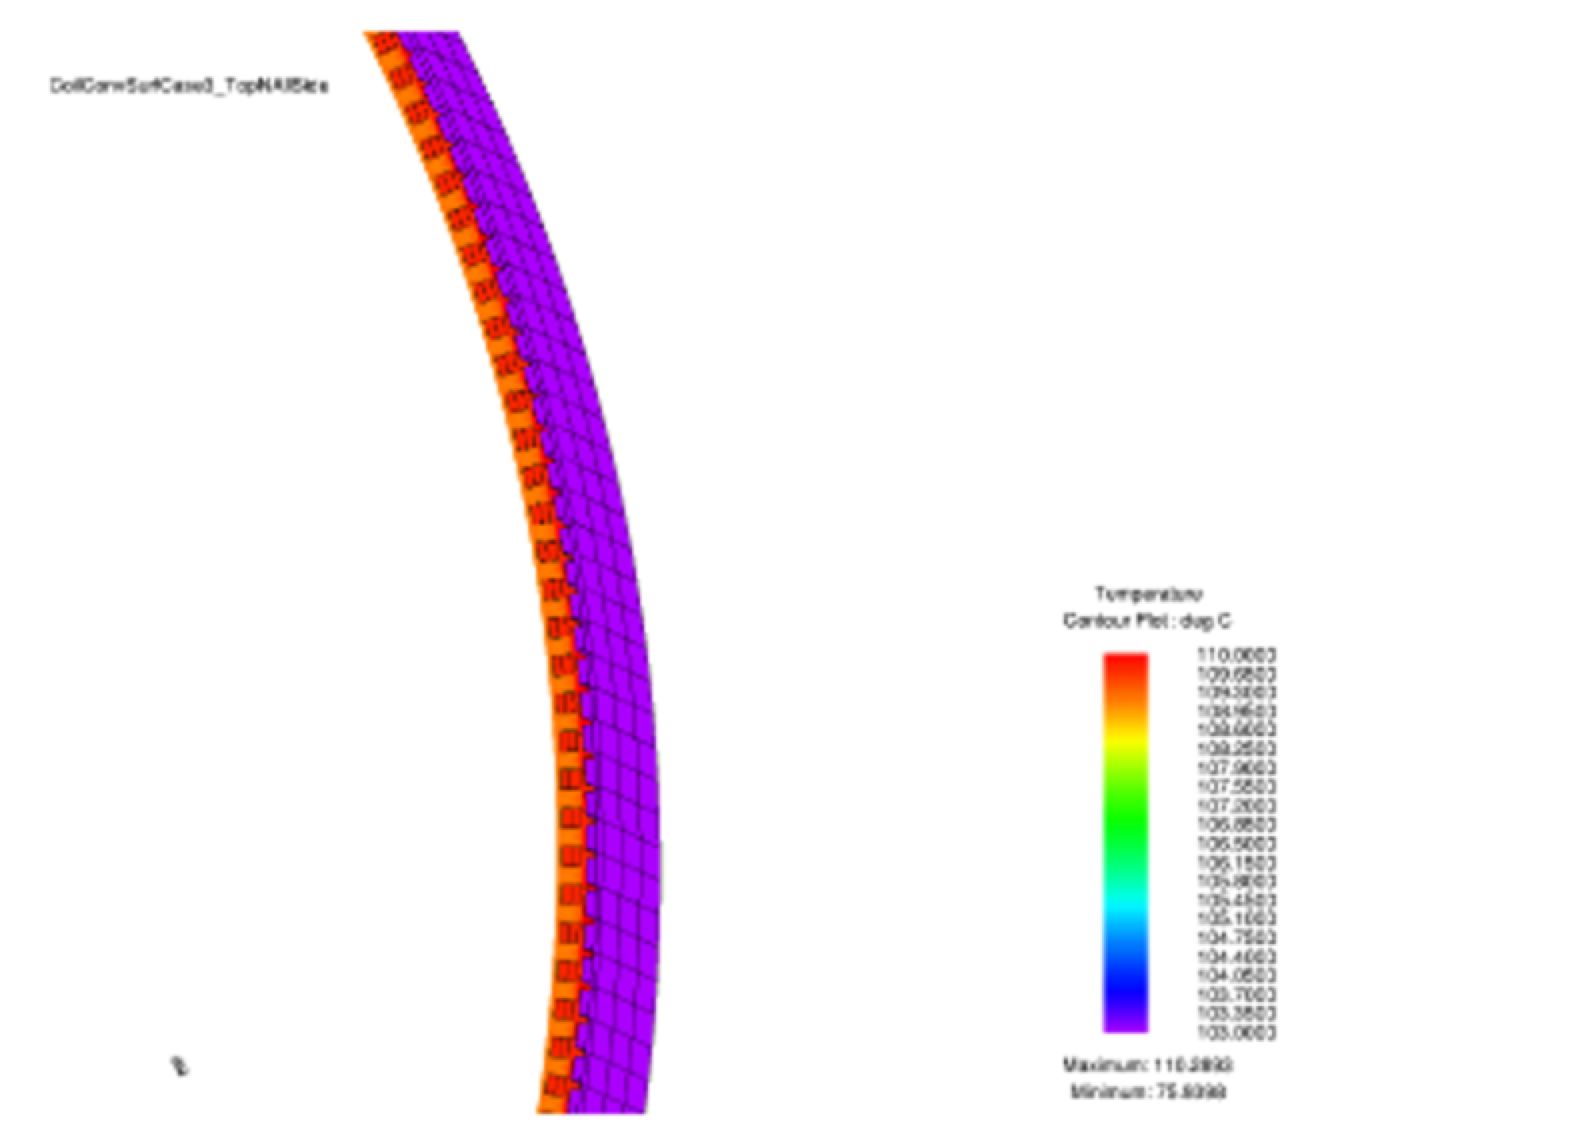

#### [Tobe]appendix  : Hollow Conductor -  HTC -> 대류열저항 해석식

@article{chen2019thermal,  title={Thermal modeling of hollow conductors for direct cooling of electrical machines},  author={Chen, Xiao and Wang, Jiabin and Griffo, Antonio and Spagnolo, Aristide},  journal={IEEE Transactions on Industrial Electronic

### 2.2 350s336p (작성중)

#### 고정자 

- Condution 조건 Equivalent Temperature Boundary 면   TopN2Side

        350p300s study2 Hollow conductor 와 동일

- 대류열저항 0.001 ([TB]appendix 와 검증)

#### 회전자

- Gas Cooling 조건 (자석 직접냉각)   -> Part2 회로 변경

    -> Part2회로는 그대로

    -> 열경계조건 추가, 열저항  7e-6, 온도 20도 고정 

#### 손실


$$
\begin{array}{|c|c|c|c|c|}
\hline \text { Loss } & & & & \\
\hline \text { Iron loss } \$[\backslash \text { mathrm }\{\mathrm{kW}\}] \$ & 54 & 69 & 62 & 71 \\
\hline \text { Coil loss } \$[\backslash \text { mathrm }\{\mathrm{kW}\}] \$ & 1030 & 799 & 593 & 641 \\
\hline \text { Magnet loss } \$[\backslash \text { mathrm }\{\mathrm{kW}\}] \$ & 230 & 239 & 139 & 303 \\
\hline \text { Total loss } \$[\backslash \text { mathrm }\{\mathrm{kW}\}] \$ & 1314 & 1108 & 794 & 1016 \\
\hline
\end{array}
\end{equation}$$


#### 결과

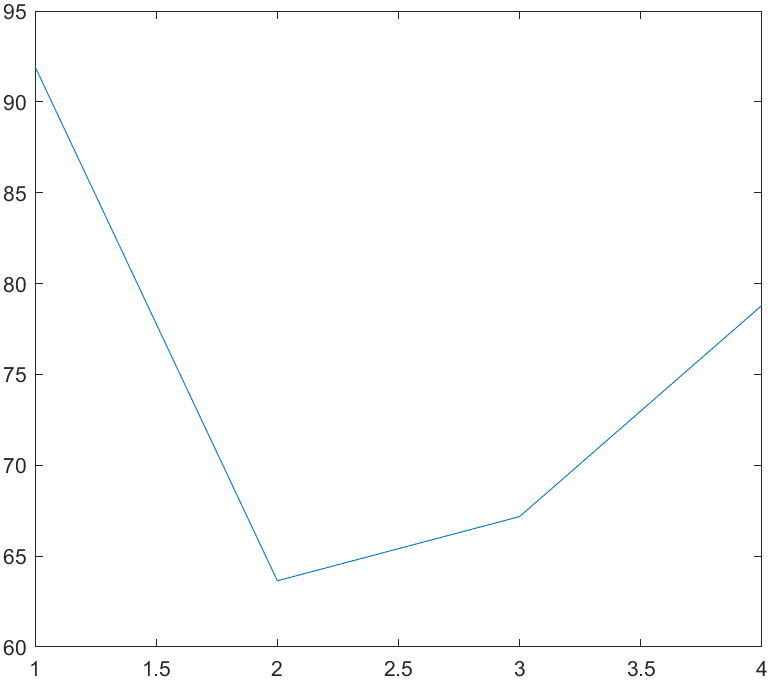

case3 

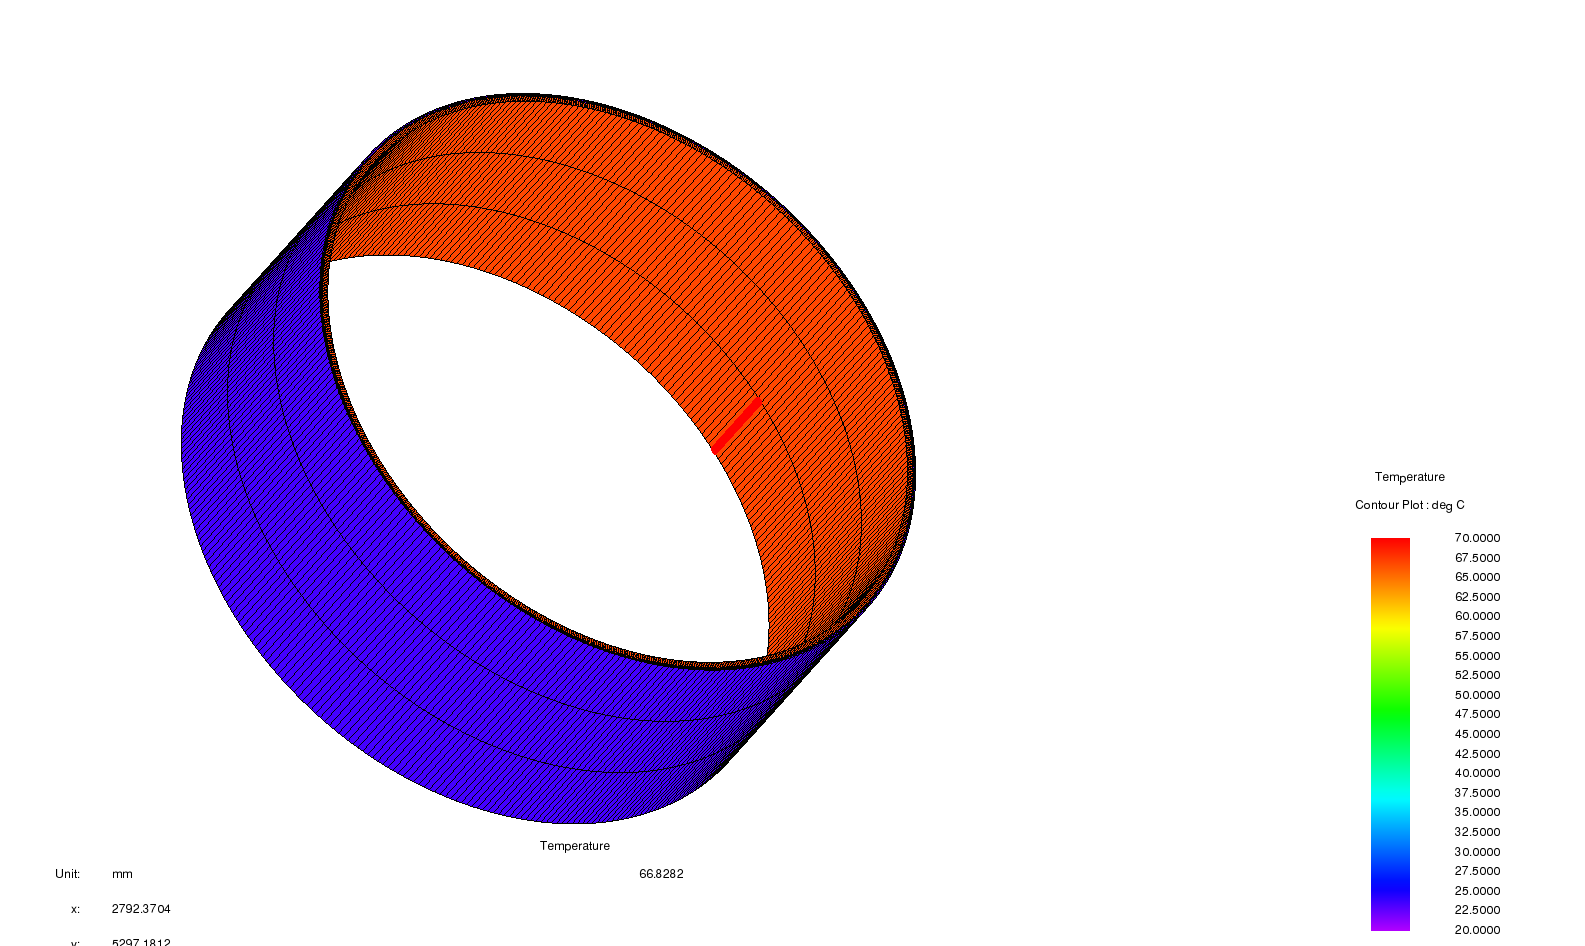

studycase =[1 2 3 4]'
Coil=	[91.9447157435	63.6440873927	67.1799927229	78.8063672212]'
plot(studycase,Coil)
